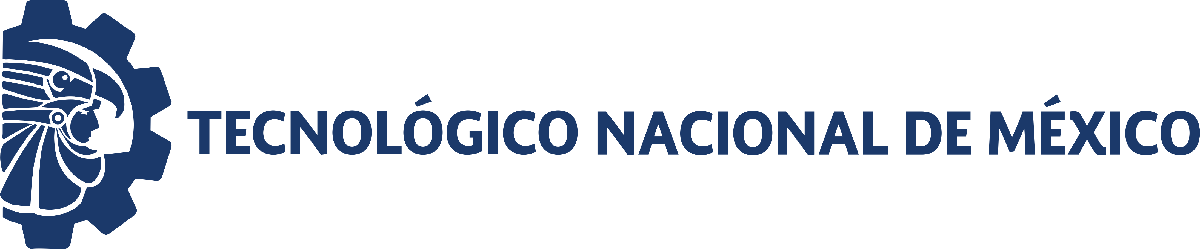                                 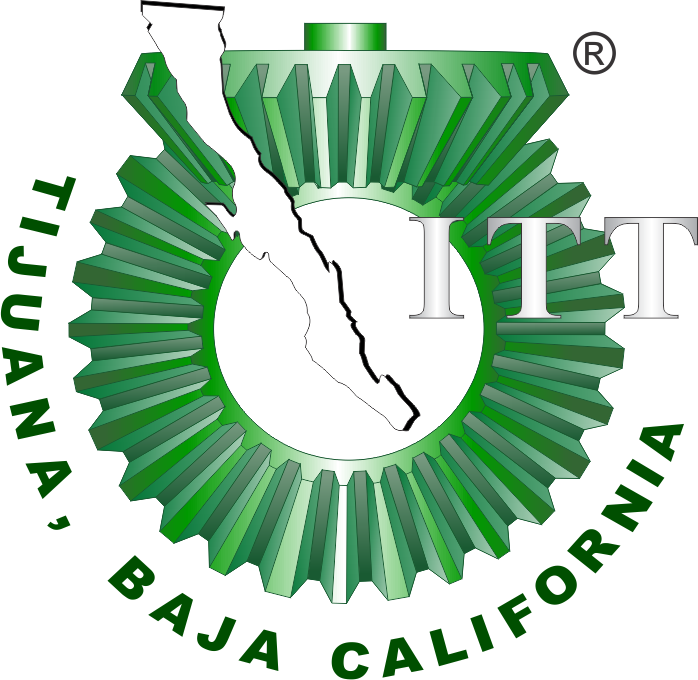

# Práctica cuatro: Sistema endocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

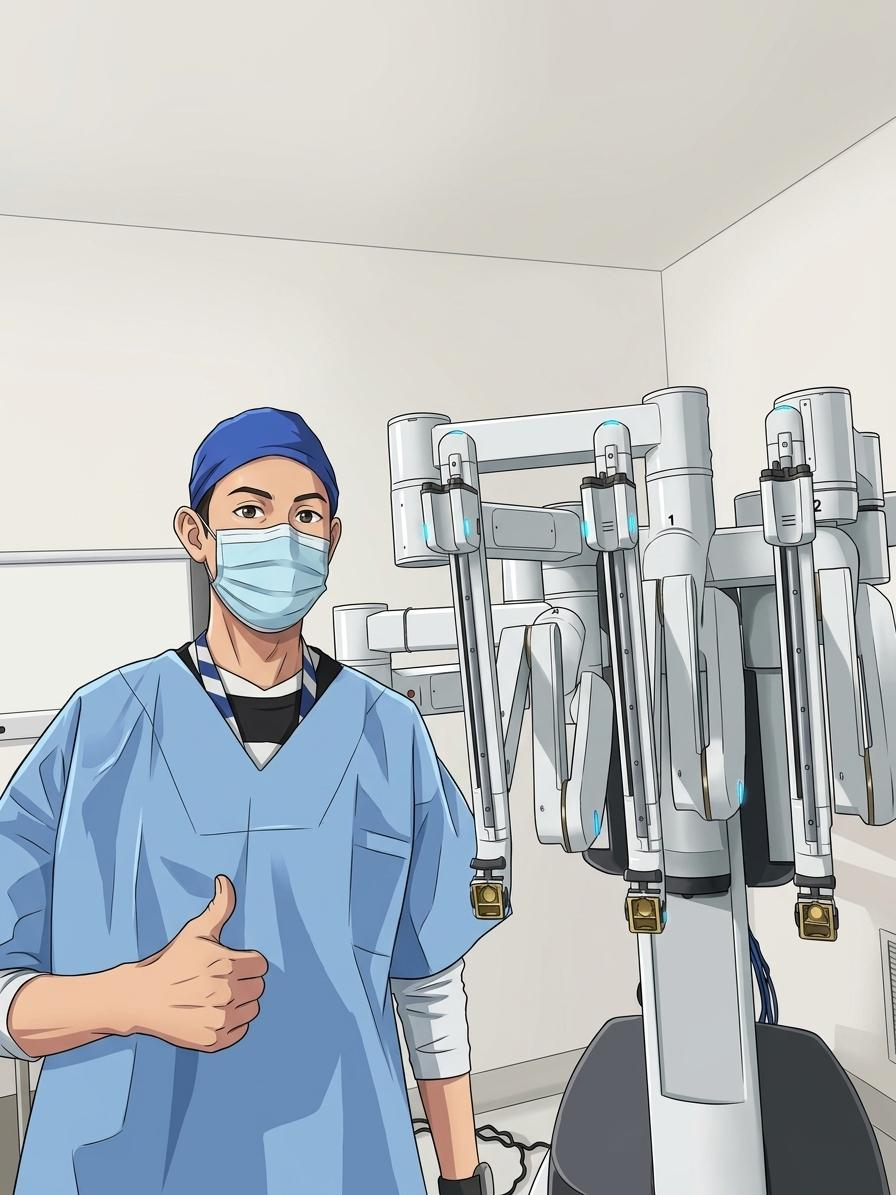

Nombre del alumno: Ernesto Jáuregui Bogarin

Número de control: 23212203

Correo institucional: l23212203**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear;
close all;
warning('off','all')
open_system('Sistema_4')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-2';
x = sim('Sistema_4',parameters);

## Respuesta Control y Caso

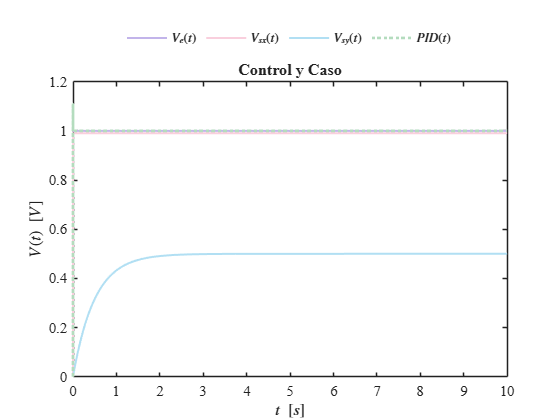

plotsignals(x.t, x.Ve, x.Vsx, x.Vsy, x.PID, 'Control y Caso')

## Funcion: Respuesta de la Simulación

function plotsignals(t, Ve, Vsx, Vsy, PID, nombre)

set(figure(), 'Color', 'w')
box on; 
hold on; 
colors = [194, 180, 234;    
    249, 207, 221;    
    177, 223, 243;    
    180, 220, 190]/255; 
colororder(colors)

P = plot(t, Ve, '-', ...    
    t, Vsx, '-', ...    
    t, Vsy, '-', ...    
    t, PID, ':', ...    
    'LineWidth', 1.5);
set(P(4), 'LineWidth', 2)
L = legend('$V_e(t)$', ...    
    '$V_{sx}(t)$', ...    
    '$V_{sy}(t)$', ...    
    '$PID(t)$');
set(L, 'Interpreter', 'Latex', ...    
    'FontSize', 10, ...    
    'Location', 'NorthOutside', ...    
    'Box', 'Off', ...    
    'Orientation', 'Horizontal');
xlabel('$t\ [s]$', 'Interpreter', 'Latex', 'FontSize', 11) 
ylabel('$V(t)\ [V]$', 'Interpreter', 'Latex', 'FontSize', 11)

xlim([0, 10]); 
xticks(0:1:10);

title(nombre)

set(gca, 'FontName', 'Times New Roman', 'FontSize', 11) 
exportgraphics(gcf, 'Control_y_Caso.pdf', 'ContentType', 'vector') 
end